# MA2011-W2 Dynamical Systems

clear all, disp(date)

18-Mar-2024


# Zero-Order Systems

Here, by zero-order systems, we mean systems for which the output ${y}(t)$ at any given time $t$ only depends on the current value of the input ${x}(t)$but not on its history. These systems can be symply modeled by a, possibly nonlinear, *algebraic equation*, e.g. 


$${y}(t) = f({x}(t), t)$$


The function $f(\cdot, t)$ might or might not depend explicitly on time $t$, in which case we denote the systems as *time-invariant*:

 
$${ y}(t) = f({x}(t))$$


The simplest case is that of linear systems, i.e. those which can be simply described by a *linear equation*


$${y}(t) = a(t)\cdot{x}(t) + { b}(t)$$


The easiest case is when the system is *Linear and Time-Invariant (LTI)*:


$${ y}(t) = a\cdot {x}(t) + { b}$$


i.e. when $a$ and ${ b}$ are constant.

# First-Order Systems (LTI) systems

Very often, the output of a system will depend also on the history of the input. Many systems of interest can be described via O*rdinary Differential Equations *(ODE). Besides its current input ${u}(t)$, the *state of the system * ${ x}(t)$ will  also depend on its time derivatives $\frac{d}{dt}{x}(t), \frac{d^2}{dt^2}{x}(t), \cdots , \frac{d^n}{dt^n}{x}(t)$, up to the *n*-th order.

First-oder systems only involve derivatives up the first order, i.e. it will only contain $\frac{d}{dt}{ x}(t)$ (denoted as  ${\dot x}(t)$, for short).

A *linear, time-invariant first-order system *can in general be described as


$${\dot x}(t) + \frac{ x(t)}{\tau} = u(t)\\
x(0) = x_0$$


where

- $\tau$ is the time constant; 

- $u(t)$is the forcing input; 

- $x_0$ is the initial condition.

In MATLAB, this can be easily written as

syms x(t) u(t) 
syms tau x0 real         
assume (tau > 0)            %% NOTE this assumption
myEQ = diff(x) == -x/tau  + u      %% fist order ODE

$$myEQ(t) = \frac{\partial }{\partial t}x\left(t\right)=u\left(t\right)-\frac{x\left(t\right)}{\tau }$$

myIC = x(0) == x0                     

$$myIC = x\left(0\right)=x_{0}$$


dsolve(myEQ, myIC)

$$ans = {\mathrm{e}}^{-\frac{t}{\tau }}\,\left(x_{0}+\int_{0}^{t}{\mathrm{e}}^{y/\tau }\,u\left(y\right)\mathrm{d}y\right)$$

## A few words on Dynamical Analogies - the heart of mechatronics

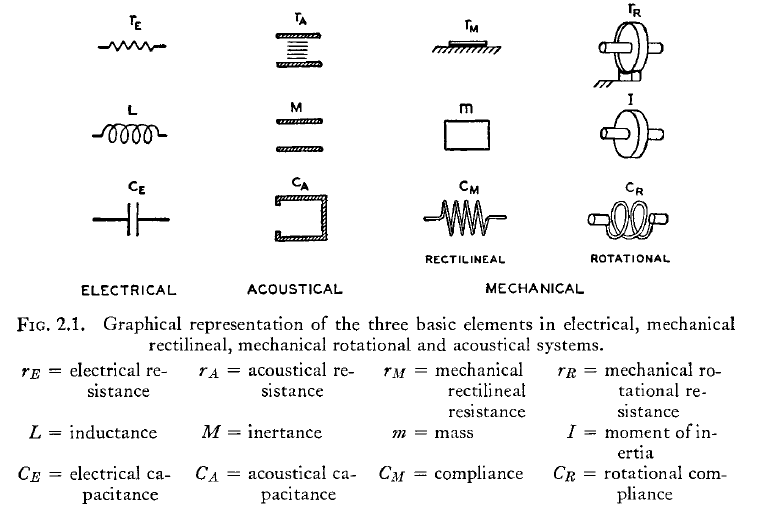

figure from [Olson 1958]

- Olson, H. F. (1958). *Dynamical analogies* (Vol. 2729). Princeton: Van Nostrand.

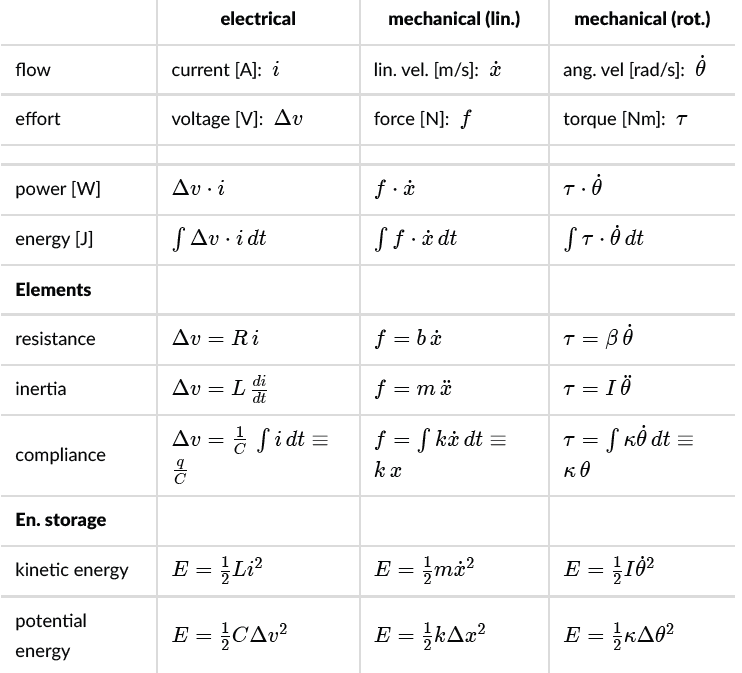

## DC Analysis (response to constant inputs)

Very often, a system is subjected to a constant input 


$${\dot x}(t) + \frac{ x(t)}{\tau} = u_0\\
x(0) = x_0$$


syms u0 real

myEQ0 = subs(myEQ, u(t), u0)

$$myEQ0(t) = \frac{\partial }{\partial t}x\left(t\right)=u_{0}-\frac{x\left(t\right)}{\tau }$$

DC_Sol = dsolve(myEQ0, myIC)

$$DC\_Sol = \tau \,u_{0}+{\mathrm{e}}^{-\frac{t}{\tau }}\,\left(x_{0}-\tau \,u_{0}\right)$$

Let's see what happens when $t\rightarrow \infty$, let's define 


$$x_{\infty} := \lim_{t\rightarrow \infty} x(t)$$


limit(DC_Sol, t, inf)

$$ans = \tau \,u_{0}$$

From this, we shall rewrite the first order equation as


$${\dot x}(t) = \frac{ x_\infty - x(t)}{\tau} \\
x(0) = x_0$$


syms x_inf real
myEQ0 = subs(myEQ, u(t), x_inf/tau)

$$myEQ0(t) = \frac{\partial }{\partial t}x\left(t\right)=\frac{x_{\inf}}{\tau }-\frac{x\left(t\right)}{\tau }$$

dsolve(myEQ0, myIC)

$$ans = x_{\inf}+{\mathrm{e}}^{-\frac{t}{\tau }}\,\left(x_{0}-x_{\inf}\right)$$

and we wish to know how it will respond. In this case, rather than a generic forcing input, we should consider a constant  input $u(t)$ and a system initially in its *zero *state, i.e. $x(0)=0$

mylegend = {};
for tau_list = [0.1 0.2 1 2 5 10]
    SOL = dsolve (subs(myEQ0, {x_inf, tau}, {5, tau_list}), 'x(0)==0')
    fplot(SOL, [0 10]); grid on; hold on
    mylegend= {mylegend{:}, ['\tau = ' num2str(tau_list) ' sec']};
    xlabel('time [sec]'); ylabel('x(t) [V]')
    title('x_\infty = 5V')
end

$$SOL = 5-5\,{\mathrm{e}}^{-10\,t}$$

$$SOL = 5-5\,{\mathrm{e}}^{-5\,t}$$

$$SOL = 5-5\,{\mathrm{e}}^{-t}$$

$$SOL = 5-5\,{\mathrm{e}}^{-\frac{t}{2}}$$

$$SOL = 5-5\,{\mathrm{e}}^{-\frac{t}{5}}$$

$$SOL = 5-5\,{\mathrm{e}}^{-\frac{t}{10}}$$

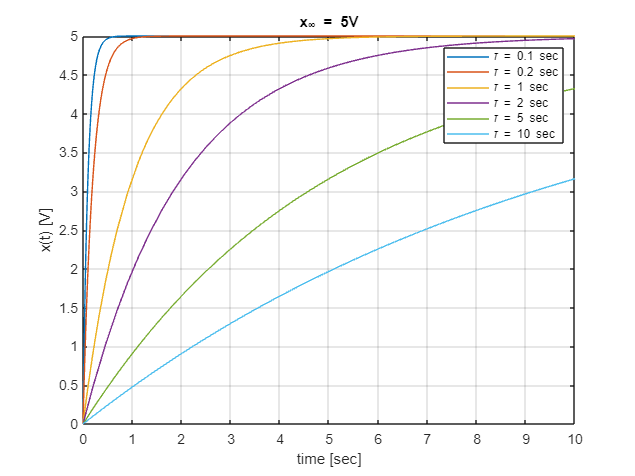

legend(mylegend);

To manually sketch exponential responses given $x_0, x_\infty, \tau$ it is useful to evalutate the time derivative of the explonential at time $t=0$, i.e.


$${\dot x}(0) = \frac{ x_\infty - x_0}{\tau}$$


subs(myEQ0, t, 0)

$$ans(t) = \left({\left(\frac{\partial }{\partial t}x\left(t\right)\right)|}_{t=0}\right)=\frac{x_{\inf}}{\tau }-\frac{x\left(0\right)}{\tau }$$

as this provides the slope of the tangent line

tau_val = 2;
x_0_val = 3;
x_inf_val = 7;
range = [0 3*tau_val];
MyExp = subs( dsolve(myEQ0, 'x(0)==x0'), {x0, x_inf, tau}, {3, 7, tau_val})

$$MyExp = 7-4\,{\mathrm{e}}^{-\frac{t}{2}}$$

MyTaylor = taylor (MyExp, t, 'Order', 2)

$$MyTaylor = 2\,t+3$$

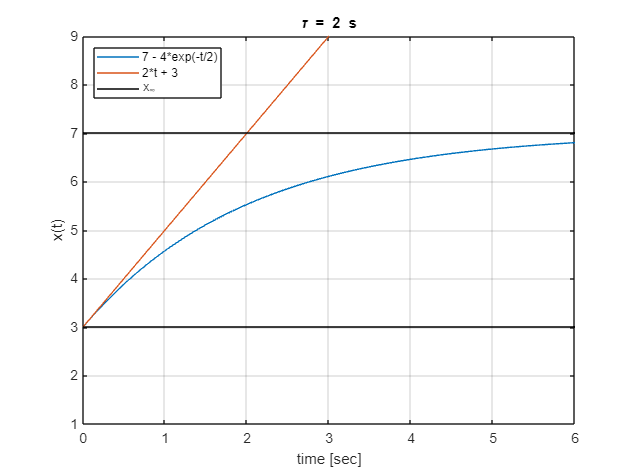

figure
fplot(MyExp, range); grid on, hold on
fplot(MyTaylor, range)
fplot(x_inf_val, 'k', range)
fplot(x_0_val, 'k', range)
ylim([x_0_val-2 x_inf_val+2])
title(['\tau = ' num2str(tau_val) ' s'])
legend(char(MyExp), char(MyTaylor), 'x_\infty', 'Location', 'NorthWest')
 xlabel('time [sec]'); ylabel('x(t)')

## AC Steady-State analysis (steady-state response to sinusoidal inputs)

AC-analysis is based on the fact that given a purely sinusoidal input, e.g. $\cos(\omega t)$, after a long time, we expect to see a purely sinusoidal output, e.g. $A_\omega \cos(\omega t+\phi_\omega)$

- at the same frequency $\omega$

- but with likely different (frequency-dependent) Amplitude $A_\omega$ and phase $\phi_\omega$


$$\cos(\omega t)\Rightarrow\|system\|\Rightarrow  A_\omega \cos(\omega t+\phi_\omega)$$


The **objective of AC analysis **is to determine Amplitude $A_\omega$ and  phase $\phi_\omega$ for every input frequency $\omega$

This can be accomplished in basically two ways

- via trigonometric manipulation (hard way)

- via complex exponentials (easy way)

Let's look at a simple case, a 1st order RC circuit

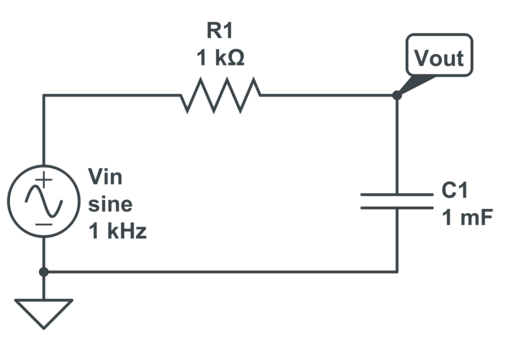

### The hard way - via trigonometry

C = 1e-3;       %% F
R = 1e3;        %% Ohms
syms phi t omega real
syms A positive     %% if we don't impose a positve value, we will get two solutions later on
V_in = cos(omega * t)

$$V\_in = \cos\left(\omega \,t\right)$$

V_out = A * cos(omega *t + phi)

$$V\_out = A\,\cos\left(\varphi +\omega \,t\right)$$

Define device equations

i = C* diff(V_out)  %% the command 'diff' takes the time derivative

$$i = -\frac{A\,\omega \,\sin\left(\varphi +\omega \,t\right)}{1000}$$

V_R = R* i

$$V\_R = -A\,\omega \,\sin\left(\varphi +\omega \,t\right)$$

Solve equations $\forall t$, in fact, only for a couple of values, then we can verify that solutions are valid at all times.

KVL = V_in == V_R + V_out

$$KVL = \cos\left(\omega \,t\right)=A\,\cos\left(\varphi +\omega \,t\right)-A\,\omega \,\sin\left(\varphi +\omega \,t\right)$$

expand (KVL)

$$ans = \cos\left(\omega \,t\right)=A\,\cos\left(\omega \,t\right)\,\cos\left(\varphi \right)-A\,\sin\left(\omega \,t\right)\,\sin\left(\varphi \right)-A\,\omega \,\cos\left(\omega \,t\right)\,\sin\left(\varphi \right)-A\,\omega \,\sin\left(\omega \,t\right)\,\cos\left(\varphi \right)$$

myEquations =  [subs(KVL, t, 0); expand(subs(KVL, t, 1/omega*pi/2))] 

$$myEquations = \left(\begin{array}{c} 1=A\,\cos\left(\varphi \right)-A\,\omega \,\sin\left(\varphi \right)\\ 0=-A\,\sin\left(\varphi \right)-A\,\omega \,\cos\left(\varphi \right) \end{array}\right)$$


myVariables = [A; phi]

$$myVariables = \left(\begin{array}{c} A\\ \varphi \end{array}\right)$$

Note that to solve this trigonometric system, you will need to make use of identities such as

cos(atan(omega))

$$ans = \frac{1}{\sqrt{\omega^{2}+1}}$$

sin(atan(omega))

$$ans = \frac{\omega }{\sqrt{\omega^{2}+1}}$$

Or ask a symbolic to solve it for you...

SOL = solve(myEquations, myVariables)

SOL = struct with fields:
      A: 1/(omega^2 + 1)^(1/2)
    phi: -2*atan(((omega^2 + 1)^(1/2) - 1)/omega)


SOL.A, SOL.phi

$$ans = \frac{1}{\sqrt{\omega^{2}+1}}$$

$$ans = -2\,\mathrm{atan}\left(\frac{\sqrt{\omega^{2}+1}-1}{\omega }\right)$$

**NOTE:** that $-2\tan^{-1}\left(
\frac{\sqrt{\omega^2 + 1} - 1}{\omega} 
\right)
\equiv -\tan^{-1}\omega$

However, this is a very cumbersome (too much trigonometry) way to proceed!!!

### The easy way via the 'complex trick'

again, start from the the time-domain equations, for simplicity let's set $\tau=1$

myEQ = subs(myEQ, tau, 1)

$$myEQ(t) = \frac{\partial }{\partial t}x\left(t\right)=u\left(t\right)-x\left(t\right)$$

Now, let's consider **complex exponentials **as inputs


$$e^{j\omega t}\Rightarrow\left|\stackrel{LTI}{ SYS}\right|\Rightarrow A_\omega \, e^{j(\omega t+\phi_\omega)}=\underbrace{A_\omega \,e^{j\phi}}_{H(j\omega)}e^{j\omega t}$$


syms H_0 complex
syms omega real
j=sqrt(-1);
myEQ_AC = subs(myEQ, {u(t), x(t)}, {exp(j*omega *t), H_0 * exp(j*omega *t)})

$$myEQ\_AC(t) = H_{0}\,\omega \,{\mathrm{e}}^{\omega \,t\,\mathrm{i}}\,\mathrm{i}={\mathrm{e}}^{\omega \,t\,\mathrm{i}}-H_{0}\,{\mathrm{e}}^{\omega \,t\,\mathrm{i}}$$

eqn_cmplx = simplify(myEQ_AC)

$$eqn\_cmplx(t) = H_{0}\,\left(1+\omega \,\mathrm{i}\right)=1$$

% simplify (real(AC_Sol_complex) - AC_Sol)
Sol_myEQ_AC = solve(eqn_cmplx, H_0)

$$Sol\_myEQ\_AC = \frac{1}{1+\omega \,\mathrm{i}}$$

Bode Plots

freq = logspace(-2, 2, 100);
H = subs(Sol_myEQ_AC,{ tau, omega}, {1, 2*pi*freq} );
figure
subplot(2,1,1)
loglog(freq, abs(H)); grid on; ylabel('amplitude'); title ('Bode Plots')
hold on
subplot(2,1,2)
semilogx(freq, angle(H)); grid on; xlabel('frequency [Hz]'); ylabel('phase [rad]')
hold on

Cut-off frequency: the frequency at which the output is reduced by -3dB (or $1/\sqrt{2}$), clearly for a first order system

omega_0 = subs(1/tau, tau, 1)

$$omega\_0 = 1$$

f_0 = omega_0/2/pi

$$f\_0 = \frac{1}{2\,\pi }$$

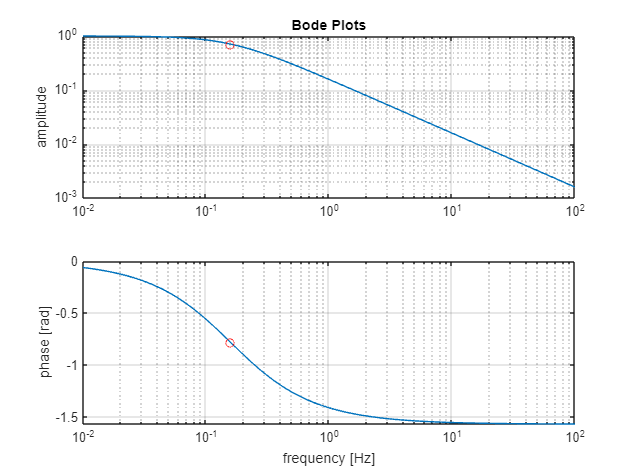

H_0 = subs(Sol_myEQ_AC,{tau, omega}, {1, 1} );
subplot(2,1,1)
loglog(omega_0/2/pi,  abs(H_0) , 'ro')
subplot(2,1,2)
semilogx(omega_0/2/pi,  angle(H_0) , 'ro')

# 2nd order dynamics

## Newton's law

Consider a mass-springer-damper case:

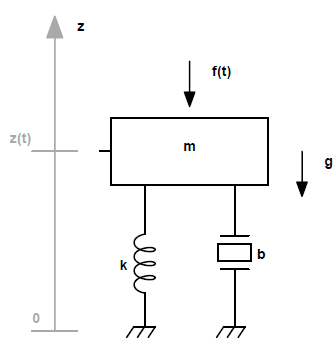

syms m b k real
syms f(t) x(t) 
eqn_Newton = f(t) == m*diff(x(t), 2)+b*diff(x(t)) + k*x(t)

$$eqn\_Newton = f\left(t\right)=m\,\frac{\partial^{2}}{\partial t^{2}}x\left(t\right)+b\,\frac{\partial }{\partial t}x\left(t\right)+k\,x\left(t\right)$$

## Time Response to constant forcing Input

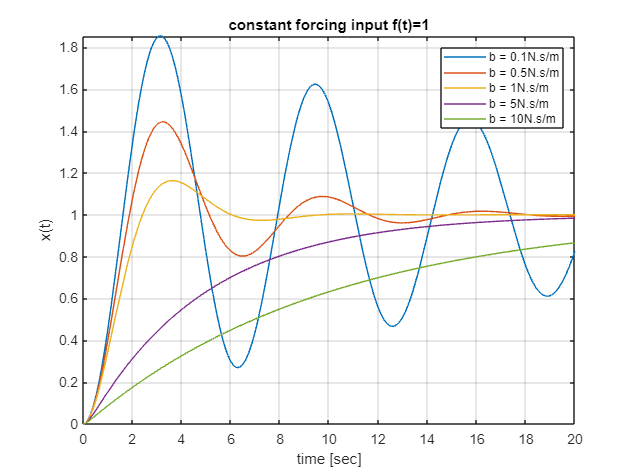

figure; 
mylegend = {};
for b_var = [0.1, 0.5, 1, 5, 10]
    mylegend = {mylegend{:}, ['b = ' num2str(b_var) 'N.s/m']};
    eqn_Newton_DC = subs(eqn_Newton, {f(t), m, b, k}, {1, 1, b_var, 1});
    Dx = diff(x);
    cond = [x(0)==0, Dx(0) == 0];
    Sol_Newton_time = dsolve(eqn_Newton_DC, cond);
    fplot(Sol_Newton_time, [0 20]); grid on; hold on
end
xlabel('time [sec]'); ylabel('x(t)'); title ('constant forcing input f(t)=1')
legend(mylegend)

## AC Analysis

syms omega real
syms F_0 X_0 complex
AC_Exp_Newton = subs(eqn_Newton, {f(t), x(t)}, {F_0*exp(j*omega*t), X_0*exp(j*omega*t)}) 

$$AC\_Exp\_Newton = F_{0}\,{\mathrm{e}}^{\omega \,t\,\mathrm{i}}=X_{0}\,k\,{\mathrm{e}}^{\omega \,t\,\mathrm{i}}+X_{0}\,b\,\omega \,{\mathrm{e}}^{\omega \,t\,\mathrm{i}}\,\mathrm{i}-X_{0}\,m\,\omega^{2}\,{\mathrm{e}}^{\omega \,t\,\mathrm{i}}$$

simplify( AC_Exp_Newton )

$$ans = X_{0}\,m\,\omega^{2}+F_{0}=X_{0}\,\left(k+b\,\omega \,\mathrm{i}\right)$$

Sol_ODE2= solve(simplify (AC_Exp_Newton) , X_0)

$$Sol\_ODE2 = \frac{F_{0}}{-m\,\omega^{2}+\mathrm{i}\,b\,\omega +k}$$

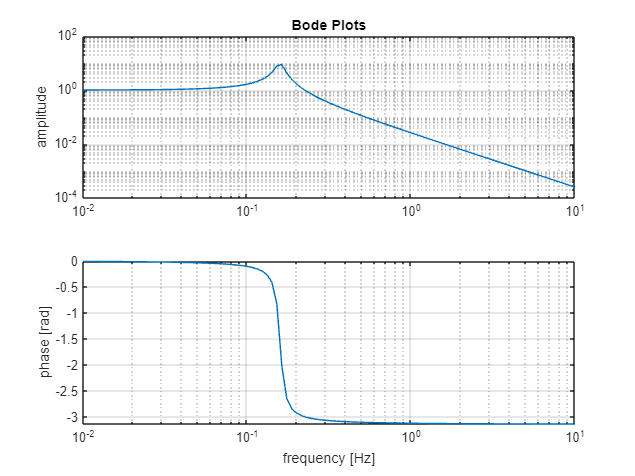


freq = logspace(-2, 1, 100);
H = subs(Sol_ODE2,{F_0, m, b, k, omega}, {1, 1, .1, 1, 2*pi*freq} );
figure
subplot(2,1,1)
loglog(freq, abs(H)); grid on; ylabel('amplitude'); title ('Bode Plots')
subplot(2,1,2)
semilogx(freq, angle(H)); grid on; xlabel('frequency [Hz]'); ylabel('phase [rad]')